# Generate functions for each equation of motion

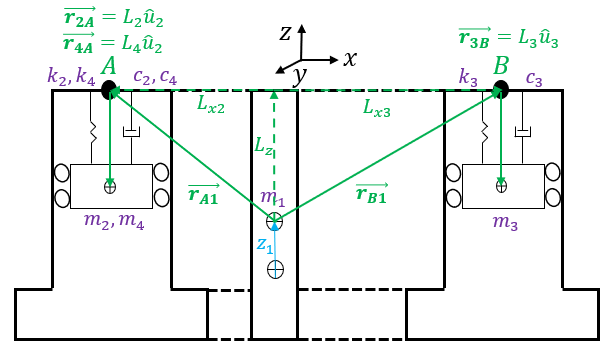

clear; clc; warning off;

## Create symbolic variables

syms x1_t(t) z1_t(t) theta_t(t) L2_t(t) L3_t(t) L4_t(t) w real % displacements as a function of time
syms x1 z1 theta L2 L3 L4 real % variables to sub in after taking derivatives
syms theta_dot z1_dot x1_dot L2_dot L3_dot L4_dot real % variables to sub in after taking derivatives
syms theta_ddot z1_ddot x1_ddot L2_ddot L3_ddot L4_ddot real % variables to sub in after taking derivatives
syms theta_w z1_w L2_w L3_w real % variables to sub in after fourier transform

syms L_x L_z real % body fixed vector components
syms L2_0 L3_0 L4_0 real % initial positions of the masses and initial rotation angle
syms m2 m3 m4 J2 J3 J4 k2 k3 k4 c2 c3 c4 real % TMD parameters
syms m1 J1 real % platform parameters
syms A11 A13 A15 A31 A33 A35 A51 A53 A55 real  % added mass parameters

## Define initial body fixed vectors and initial rotation matrix

u_0 = [0;-1];

## Define body fixed vectors and rotation matrix

R = [cos(theta_t(t)) -sin(theta_t(t))
     sin(theta_t(t))  cos(theta_t(t))];

u = R*u_0;

r_A1 = R*[-L_x;L_z];
r_B1 = R*[2*L_x;L_z];
r_C1 = R*[-L_x;L_z];

r_2A = L2_t(t)*u;
r_3B = L3_t(t)*u;
r_4C = L4_t(t)*u;

r_2A_dot = diff(r_2A,t);
r_3B_dot = diff(r_3B,t);
r_4C_dot = diff(r_4C,t);

## Define global vectors

r_1 = [x1_t(t);z1_t(t)];

r_A = r_A1 + r_1;
r_B = r_B1 + r_1;
r_C = r_C1 + r_1;

r_2 = r_A + r_2A;
r_3 = r_B + r_3B;
r_4 = r_C + r_4C;

r_A_dot = diff(r_A,t);
r_B_dot = diff(r_B,t);
r_C_dot = diff(r_C,t);

r_2_dot = diff(r_2,t);
r_3_dot = diff(r_3,t);
r_4_dot = diff(r_4,t);

## Define positions and velocities of A and B over time

x_A = r_A(1);
x_B = r_B(1);
x_C = r_C(1);

z_A = r_A(2);
z_B = r_B(2);
z_C = r_C(2);

x_A_dot = r_A_dot(1);
x_B_dot = r_B_dot(1);
x_C_dot = r_C_dot(1);

z_A_dot = r_A_dot(2);
z_B_dot = r_B_dot(2);
z_C_dot = r_C_dot(2);

## Define positions and velocities of masses over time

x_2 = r_2(1);
x_3 = r_3(1);
x_4 = r_4(1);

z_2 = r_2(2);
z_3 = r_3(2);
z_4 = r_4(2);

x_2_dot = r_2_dot(1);
x_3_dot = r_3_dot(1);
x_4_dot = r_4_dot(1);

z_2_dot = r_2_dot(2);
z_3_dot = r_3_dot(2);
z_4_dot = r_4_dot(2);

## Define Energies

T = (1/2)*m1*diff(x1_t(t),t)^2 + (1/2)*m1*diff(z1_t(t),t)^2 + ...
    + (1/2)*J1*diff(theta_t(t),t)^2 + (1/2)*J2*diff(theta_t(t),t)^2 + ...
    + (1/2)*J3*diff(theta_t(t),t)^2 + (1/2)*J4*diff(theta_t(t),t)^2 + ... 
    + (1/2)*m2*x_2_dot^2 + (1/2)*m2*z_2_dot^2 + (1/2)*m3*x_3_dot^2 + (1/2)*m3*z_3_dot^2 + ...
    + (1/2)*m4*x_4_dot^2 + (1/2)*m4*z_4_dot^2;

U = (1/2)*k2*(L2_0 - L2_t(t))^2 + (1/2)*k3*(L3_0 - L3_t(t))^2  + (1/2)*k4*(L4_0 - L4_t(t))^2;

R = (1/2)*c2*(diff(L2_t(t),t))^2 + (1/2)*c3*(diff(L3_t(t),t))^2 + (1/2)*c4*(diff(L4_t(t),t))^2;

L = T - U;

## Calculate the equations of motion using the lagrange equation


$$\frac{d}{\textrm{dt}}\frac{\partial L}{{\partial \dot{q} }_i }-\frac{\partial L}{{\partial q}_i }+\frac{\partial R}{{\partial \dot{q} }_i }=0$$


EOM_x1_t = diff(diff(L,diff(x1_t,t)),t) - diff(L,x1_t) + diff(R,diff(x1_t,t)) == 0;
EOM_z1_t = diff(diff(L,diff(z1_t,t)),t) - diff(L,z1_t) + diff(R,diff(z1_t,t)) == 0;
EOM_theta_t = diff(diff(L,diff(theta_t,t)),t) - diff(L,theta_t) + diff(R,diff(theta_t,t)) == 0;
EOM_L2_t = diff(diff(L,diff(L2_t,t)),t) - diff(L,L2_t) + diff(R,diff(L2_t,t)) == 0;
EOM_L3_t = diff(diff(L,diff(L3_t,t)),t) - diff(L,L3_t) + diff(R,diff(L3_t,t)) == 0;
EOM_L4_t = diff(diff(L,diff(L4_t,t)),t) - diff(L,L4_t) + diff(R,diff(L4_t,t)) == 0;

## Substitute in the non time dependent parameters

EOM_x1 = subs(EOM_x1_t,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
EOM_x1 = subs(EOM_x1,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
EOM_x1 = subs(EOM_x1,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
EOM_x1 = subs(EOM_x1,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
EOM_x1 = subs(EOM_x1,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
EOM_x1 = subs(EOM_x1,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

EOM_z1 = subs(EOM_z1_t,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
EOM_z1 = subs(EOM_z1,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
EOM_z1 = subs(EOM_z1,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
EOM_z1 = subs(EOM_z1,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
EOM_z1 = subs(EOM_z1,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
EOM_z1 = subs(EOM_z1,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

EOM_theta = subs(EOM_theta_t,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
EOM_theta = subs(EOM_theta,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
EOM_theta = subs(EOM_theta,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
EOM_theta = subs(EOM_theta,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
EOM_theta = subs(EOM_theta,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
EOM_theta = subs(EOM_theta,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

EOM_L2 = subs(EOM_L2_t,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
EOM_L2 = subs(EOM_L2,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
EOM_L2 = subs(EOM_L2,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
EOM_L2 = subs(EOM_L2,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
EOM_L2 = subs(EOM_L2,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
EOM_L2 = subs(EOM_L2,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

EOM_L3 = subs(EOM_L3_t,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
EOM_L3 = subs(EOM_L3,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
EOM_L3 = subs(EOM_L3,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
EOM_L3 = subs(EOM_L3,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
EOM_L3 = subs(EOM_L3,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
EOM_L3 = subs(EOM_L3,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

EOM_L4 = subs(EOM_L4_t,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
EOM_L4 = subs(EOM_L4,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
EOM_L4 = subs(EOM_L4,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
EOM_L4 = subs(EOM_L4,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
EOM_L4 = subs(EOM_L4,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
EOM_L4 = subs(EOM_L4,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

## Handle coupled added mass terms

A1 = [A11 A13 A15];
A3 = [A31 A33 A35];
A5 = [A51 A53 A55];
x = [x1_ddot;z1_ddot;theta_ddot];

EOM_x1 = lhs(EOM_x1) + A1*x == 0;
EOM_z1 = lhs(EOM_z1) + A3*x == 0;
EOM_theta = lhs(EOM_theta) + A5*x == 0;

## Split equations into matrices

[A,b] = equationsToMatrix([EOM_x1,EOM_z1,EOM_theta,EOM_L2,EOM_L3,EOM_L4],[x1_ddot,z1_ddot,theta_ddot,L2_ddot,L3_ddot,L4_ddot]);
left_hand_matrix = A;
right_hand_vector = b;

## Define matlab function for each matrix

matlabFunction(left_hand_matrix,'File','ode/calculate_left_hand_matrix_TMD');
matlabFunction(right_hand_vector,'File','ode/calculate_right_hand_vector_TMD');

## Sub values into energies

T = subs(T,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
T = subs(T,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
T = subs(T,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
T = subs(T,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
T = subs(T,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
T = subs(T,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

U = subs(U,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
U = subs(U,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
U = subs(U,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
U = subs(U,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
U = subs(U,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
U = subs(U,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

## Define matlab function for energies

matlabFunction(T,'File','energy/calculate_kinetic_energy_TMD');
matlabFunction(U,'File','energy/calculate_potential_energy_TMD');

## Sub in values for positions

x_A = subs(x_A,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
x_A = subs(x_A,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
x_A = subs(x_A,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
x_A = subs(x_A,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
x_A = subs(x_A,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
x_A = subs(x_A,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

x_B = subs(x_B,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
x_B = subs(x_B,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
x_B = subs(x_B,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
x_B = subs(x_B,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
x_B = subs(x_B,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
x_B = subs(x_B,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

x_C = subs(x_C,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
x_C = subs(x_C,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
x_C = subs(x_C,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
x_C = subs(x_C,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
x_C = subs(x_C,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
x_C = subs(x_C,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

x_2 = subs(x_2,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
x_2 = subs(x_2,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
x_2 = subs(x_2,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
x_2 = subs(x_2,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
x_2 = subs(x_2,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
x_2 = subs(x_2,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

x_3 = subs(x_3,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
x_3 = subs(x_3,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
x_3 = subs(x_3,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
x_3 = subs(x_3,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
x_3 = subs(x_3,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
x_3 = subs(x_3,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

x_4 = subs(x_4,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
x_4 = subs(x_4,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
x_4 = subs(x_4,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
x_4 = subs(x_4,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
x_4 = subs(x_4,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
x_4 = subs(x_4,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

z_A = subs(z_A,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
z_A = subs(z_A,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
z_A = subs(z_A,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
z_A = subs(z_A,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
z_A = subs(z_A,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
z_A = subs(z_A,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

z_B = subs(z_B,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
z_B = subs(z_B,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
z_B = subs(z_B,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
z_B = subs(z_B,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
z_B = subs(z_B,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
z_B = subs(z_B,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

z_C = subs(z_C,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
z_C = subs(z_C,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
z_C = subs(z_C,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
z_C = subs(z_C,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
z_C = subs(z_C,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
z_C = subs(z_C,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

z_2 = subs(z_2,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
z_2 = subs(z_2,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
z_2 = subs(z_2,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
z_2 = subs(z_2,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
z_2 = subs(z_2,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
z_2 = subs(z_2,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

z_3 = subs(z_3,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
z_3 = subs(z_3,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
z_3 = subs(z_3,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
z_3 = subs(z_3,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
z_3 = subs(z_3,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
z_3 = subs(z_3,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

z_4 = subs(z_4,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
z_4 = subs(z_4,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
z_4 = subs(z_4,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
z_4 = subs(z_4,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
z_4 = subs(z_4,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
z_4 = subs(z_4,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

## Sub in values for velocities

x_A_dot = subs(x_A_dot,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
x_A_dot = subs(x_A_dot,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
x_A_dot = subs(x_A_dot,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
x_A_dot = subs(x_A_dot,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
x_A_dot = subs(x_A_dot,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
x_A_dot = subs(x_A_dot,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

x_B_dot = subs(x_B_dot,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
x_B_dot = subs(x_B_dot,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
x_B_dot = subs(x_B_dot,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
x_B_dot = subs(x_B_dot,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
x_B_dot = subs(x_B_dot,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
x_B_dot = subs(x_B_dot,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

x_C_dot = subs(x_C_dot,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
x_C_dot = subs(x_C_dot,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
x_C_dot = subs(x_C_dot,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
x_C_dot = subs(x_C_dot,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
x_C_dot = subs(x_C_dot,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
x_C_dot = subs(x_C_dot,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

x_2_dot = subs(x_2_dot,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
x_2_dot = subs(x_2_dot,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
x_2_dot = subs(x_2_dot,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
x_2_dot = subs(x_2_dot,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
x_2_dot = subs(x_2_dot,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
x_2_dot = subs(x_2_dot,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

x_3_dot = subs(x_3_dot,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
x_3_dot = subs(x_3_dot,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
x_3_dot = subs(x_3_dot,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
x_3_dot = subs(x_3_dot,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
x_3_dot = subs(x_3_dot,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
x_3_dot = subs(x_3_dot,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

x_4_dot = subs(x_4_dot,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
x_4_dot = subs(x_4_dot,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
x_4_dot = subs(x_4_dot,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
x_4_dot = subs(x_4_dot,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
x_4_dot = subs(x_4_dot,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
x_4_dot = subs(x_4_dot,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

z_A_dot = subs(z_A_dot,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
z_A_dot = subs(z_A_dot,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
z_A_dot = subs(z_A_dot,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
z_A_dot = subs(z_A_dot,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
z_A_dot = subs(z_A_dot,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
z_A_dot = subs(z_A_dot,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

z_B_dot = subs(z_B_dot,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
z_B_dot = subs(z_B_dot,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
z_B_dot = subs(z_B_dot,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
z_B_dot = subs(z_B_dot,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
z_B_dot = subs(z_B_dot,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
z_B_dot = subs(z_B_dot,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

z_C_dot = subs(z_C_dot,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
z_C_dot = subs(z_C_dot,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
z_C_dot = subs(z_C_dot,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
z_C_dot = subs(z_C_dot,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
z_C_dot = subs(z_C_dot,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
z_C_dot = subs(z_C_dot,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

z_2_dot = subs(z_2_dot,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
z_2_dot = subs(z_2_dot,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
z_2_dot = subs(z_2_dot,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
z_2_dot = subs(z_2_dot,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
z_2_dot = subs(z_2_dot,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
z_2_dot = subs(z_2_dot,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

z_3_dot = subs(z_3_dot,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
z_3_dot = subs(z_3_dot,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
z_3_dot = subs(z_3_dot,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
z_3_dot = subs(z_3_dot,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
z_3_dot = subs(z_3_dot,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
z_3_dot = subs(z_3_dot,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

z_4_dot = subs(z_4_dot,[x1_t,diff(x1_t,t),diff(x1_t,t,t)],[x1,x1_dot,x1_ddot]);
z_4_dot = subs(z_4_dot,[z1_t,diff(z1_t,t),diff(z1_t,t,t)],[z1,z1_dot,z1_ddot]);
z_4_dot = subs(z_4_dot,[theta_t,diff(theta_t,t),diff(theta_t,t,t)],[theta,theta_dot,theta_ddot]);
z_4_dot = subs(z_4_dot,[L2_t,diff(L2_t,t),diff(L2_t,t,t)],[L2,L2_dot,L2_ddot]);
z_4_dot = subs(z_4_dot,[L3_t,diff(L3_t,t),diff(L3_t,t,t)],[L3,L3_dot,L3_ddot]);
z_4_dot = subs(z_4_dot,[L4_t,diff(L4_t,t),diff(L4_t,t,t)],[L4,L4_dot,L4_ddot]);

## Define matlab function for positions and velocities

matlabFunction([x_A,x_B,x_C,z_A,z_B,z_C],'File','positions/calculate_platform_positions');
matlabFunction([x_A_dot,x_B_dot,x_C_dot,z_A_dot,z_B_dot,z_C_dot],'File','positions/calculate_platform_velocities');
matlabFunction([x_2,x_3,x_4,z_2,z_3,z_4],'File','positions/calculate_mass_positions');
matlabFunction([x_2_dot,x_3_dot,x_4_dot,z_2_dot,z_3_dot,z_4_dot],'File','positions/calculate_mass_velocities');
